%wczytanie koniecznych parametrów i wyliczenie wzocnień oraz punktów równowagi 
clear all
close all
run("wyliczanie_jacobianow_oraz_p_row.mlx")

ans = 0.0100

mwag_cal = -18.2574

close all
initial_x = 0.013;
max_x = 0.0212;
expected_z = 0.01;
KW = -[polyval(p_z,expected_z) polyval(p_v,expected_z) polyval(p_i,expected_z)];
Kw = -[polyval(p_z,expected_z)*max_x polyval(p_v,expected_z) polyval(p_i,expected_z)*3];


GENERAL INFO

obsInfo = rlNumericSpec([4 1], LowerLimit=[-1 -1 -1 0]', UpperLimit=[ 1 1 1 1]');
actInfo = rlNumericSpec([1 1],"UpperLimit",1,"LowerLimit",-1); 


obsInfo.Name = "observations";
obsInfo.Description = "position z, velocity v, current expected_z";
actInfo.Name = "control";

env = rlSimulinkEnv("MODEL_neural_multi","MODEL_neural_multi/controller",obsInfo,actInfo);
env.ResetFcn = @start_multi;

Ts = 5e-3;
Tf = 0.5;
rng(0,"twister");

CRITIC

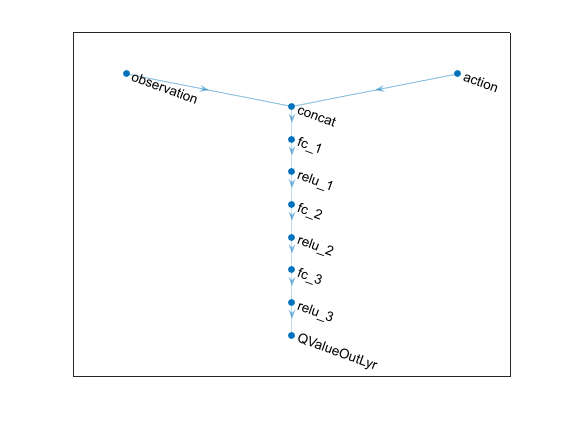

% Observation and action paths
% obsPath = featureInputLayer(3,Name="observation");
% actPath = featureInputLayer(1,Name="action");
% 
% % Common path
% commonPath = [
%     concatenationLayer(1,2,Name="concat")
%     quadraticLayer
%     fullyConnectedLayer(1,Name="value", ...
%         Bias=-0.5, Weights= [-1.1, -0.1, -1.1, -0.1, -0.1, -1.1 -0.1 -0.1 -0.1 -1.1 ])
%     ];
% 
% %BiasLearnRateFactor=0,
% criticNet = dlnetwork;
% criticNet = addLayers(criticNet,obsPath);
% criticNet = addLayers(criticNet,actPath);
% criticNet = addLayers(criticNet,commonPath);
% 
% criticNet = connectLayers(criticNet,"observation","concat/in1");
% criticNet = connectLayers(criticNet,"action","concat/in2");

observationPath = [
    featureInputLayer(4,Name="observation")
    concatenationLayer(1,2,Name="concat")
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(1,Name="QValueOutLyr")
    ];
actionPath = featureInputLayer(1,Name="action");


criticNet = dlnetwork;
criticNet = addLayers(criticNet, observationPath);
criticNet = addLayers(criticNet, actionPath);
criticNet = connectLayers(criticNet,"action","concat/in2");

plot(criticNet)

summary(initialize(criticNet))


   Initialized: true

   Number of learnables: 3k

   Inputs:
      1   'observation'   4 features
      2   'action'        1 features




% criticNet = initialize(criticNet);
% summary(criticNet)
critic = rlQValueFunction(criticNet, ...
    obsInfo,actInfo, ...
    ObservationInputNames="observation", ...
    ActionInputNames="action", ...
    UseDevice='gpu');


% commonPath = [
%     featureInputLayer(64, Name="observation")
%     fullyConnectedLayer(64)
%     reluLayer()
%     fullyConnectedLayer(32)
% 
% ];
% 
% % Define the mean path
% meanPath = [
%     fullyConnectedLayer(16, Name="Multiplier")
%     tanhLayer% Element-wise multiplication layer
%     fullyConnectedLayer(1, Name="actionMean")
% ];
% 
% % Define the standard deviation path
% stdPath = [
%     fullyConnectedLayer(1, Name="stdFC", WeightsInitializer='zeros', Bias=[0.1])
%     softplusLayer(Name="actionStd")
% ];
% 
% % Create the actor network (dlnetwork object)
% actorNet = dlnetwork;
% 
% % Add the layers to the network
% actorNet = addLayers(actorNet, commonPath);
% actorNet = addLayers(actorNet, meanPath);
% actorNet = addLayers(actorNet, stdPath);
% 
% % Connect the layers
% actorNet = connectLayers(actorNet, "observation", "Multiplier/in");  % Connecting to the mean path
% actorNet = connectLayers(actorNet, "observation", "stdFC/in");   % Connecting to the std path
% 
% 
% % Display the summary of the network
% summary(initialize(actorNet))
% plot(actorNet)

% % Create the actor using the predefined network and the observation and action info
% actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
%     ObservationInputNames="observation", ...
%     ActionMeanOutputNames="actionMean", ...
%     ActionStandardDeviationOutputNames="actionStd", ...
%     UseDevice='gpu');


commonPath = [
    featureInputLayer(4,Name="observation")
    % fullyConnectedLayer(64)
    % tanhLayer()
    % fullyConnectedLayer(32)
    %reluLayer(Name="commonPath")
    ];
meanPath = [
    fullyConnectedLayer(2,Name="meanFC")
    tanhLayer(Name="tanh")
    fullyConnectedLayer(1,Name="actionMean")
    ];
stdPath = [
    fullyConnectedLayer(1,Name="stdFC", WeightsInitializer='zeros', Bias=[0.1])
    softplusLayer(Name="actionStd")
    ];


actorNet = dlnetwork;
actorNet = addLayers(actorNet,commonPath);
actorNet = addLayers(actorNet,meanPath);
actorNet = addLayers(actorNet,stdPath);
actorNet = connectLayers(actorNet,"observation","meanFC/in");
actorNet = connectLayers(actorNet,"observation","stdFC/in");
summary(initialize(actorNet))


   Initialized: true

   Number of learnables: 18

   Inputs:
      1   'observation'   4 features



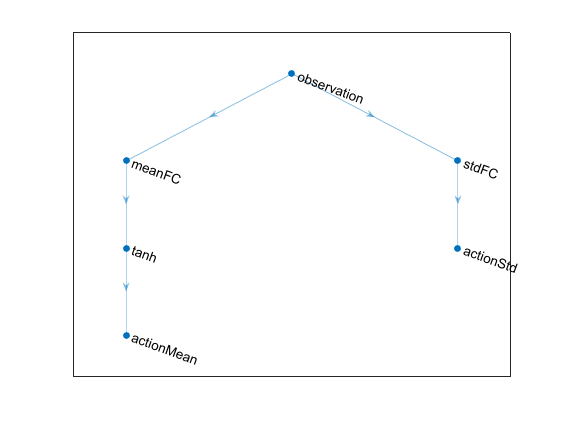

plot(actorNet)


% Create the actor using the predefined network and the observation and action info
actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
    ObservationInputNames="observation", ...
    ActionMeanOutputNames="actionMean", ...
    ActionStandardDeviationOutputNames="actionStd", ...
    UseDevice='gpu');

Unrecognized function or variable 'obsInfo'.


% Display the actor details
disp(actor)


AGENT


agentOpts = rlSACAgentOptions( ...
    SampleTime             = Ts, ...
    ExperienceBufferLength = 1e4, ...
    NumWarmStartSteps      = 64, ...
    MiniBatchSize          = 64, ...
    DiscountFactor         = 0.95, ...
    PolicyUpdateFrequency  = 2, ...
    TargetUpdateFrequency  = 1 ...
    );

agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 5e-4;
agentOpts.ActorOptimizerOptions.GradientThreshold = 100;

%agentOpts.ActorOptimizerOptions.OptimizerParameters

agentOpts.CriticOptimizerOptions(1).Algorithm = "adam";
agentOpts.CriticOptimizerOptions(1).LearnRate = 1e-3;
agentOpts.CriticOptimizerOptions(1).GradientThreshold = 100;

% agentOpts.CriticOptimizerOptions(2).Algorithm = "adam";
% agentOpts.CriticOptimizerOptions(2).LearnRate = 1e-3;
% agentOpts.CriticOptimizerOptions(2).GradientThreshold = 10;

%agentOpts.EntropyWeightOptions.EntropyWeight = 5e-3;
% agentOpts.EntropyWeightOptions.LearnRate = 5e-3;
% agentOpts.EntropyWeightOptions.GradientThreshold = 1;


agent = rlSACAgent(actor,critic,agentOpts);

% training options
trainOpts = rlTrainingOptions(...
    MaxEpisodes=4000, ...
    MaxStepsPerEpisode=floor(Tf/Ts), ...
    ScoreAveragingWindowLength=100, ...
    StopTrainingCriteria= "none" , ...
    SimulationStorageType="none");
%     StopTrainingCriteria= "EpisodeReward" , ...
    % StopTrainingValue = 2700, ...
% agent evaluation
evl = rlEvaluator(EvaluationFrequency=25, NumEpisodes=5);

    trainingOpts.UseParallel = true;
    trainingOpts.ParallelizationOptions.Mode = "sync";
    trainingOpts.ParallelizationOptions.StepsUntilDataIsSent = -1;


doTraining = 1;

if doTraining
    trainingStats = train(agent,env,trainOpts,Evaluator=evl);
    save("multi_SAC_64_32-16.mat","agent")
end